# **Live cell analysis**

**YFP1: Cdt1 IF stain**

**POI(:,3): CRL4Cdt2 activation time**

**cdk: Cyclin E/A-CDK activity**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'DMSO no dox',2:3,2,1:4,[0 0 0]; %1    
        'DMSO dox',4:7,2,1:4,[0 0 0]; %1
        
        'ATRi no dox',2:3,3,1:4,[0 0 0]; %1    
        'ATRi dox',4:7,3,1:4,[0 0 0]; %1
        
        'ATMi no dox',2:3,4,1:4,[0 0 0]; %1    
        'ATMi dox',4:7,4,1:4,[0 0 0]; %1
        
        'ATR/Mi no dox',2:3,5,1:4,[0 0 0]; %1    
        'ATR/Mi dox',4:7,5,1:4,[0 0 0]; %1
        
        'DNAPKi no dox',2:3,6,1:4,[0 0 0]; %1    
        'DNAPKi dox',4:7,6,1:4,[0 0 0]; %1
        
        'Wee1i no dox',2:3,7,1:4,[0 0 0]; %1    
        'Wee1i dox',4:7,7,1:4,[0 0 0]; %1
        
        'HU no dox',2:3,8,1:4,[0 0 0]; %1       
        'HU dox',4:7,8,1:4,[0 0 0]; %1
        
        'Aphi no dox',2:3,9,1:4,[0 0 0]; %1    
        'Aphi dox',4:7,9,1:4,[0 0 0]; %1

    };

% 
 load([dataDir filesep 'C130_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 75;
frameEdU = 0;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

POI_time = arrayfun(@(x) (numFrames - x.POI)/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};

Quality gate

for i=1:length(S)
    data = S(i);
    cdk_gate = false(size(data.traceStats,1),1);
    crl_gate = false(size(data.traceStats,1),1);
    for c = 1:size(data.traceStats,1)
        if data.traceStats(c,1) == 30  & ~any(data.cdk(c,30:35) > .8)
            cdk_gate(c) = true;
        end
        
        if data.traceStats(c,1) == 30  & data.POI(c,3) + 10 <= numFrames
            if data.crlNormAct(c,data.POI(c,3) + 10) < 0.75 & ...
                    data.crlNormAct(c,data.POI(c,3) - 5) < 1 & data.cdk(c,data.POI(c,3)) > .7
                crl_gate(c) = true;
            end
        end
    end
    S(i).cdk_gate = cdk_gate;
    S(i).crl_gate = crl_gate;
end

## **Plot traces aligned**

rng(20)
conds=[1];
poiAlign = [3];
alignNames = {'CRL4 on'};
cols = [0 113 188]/255;
for p = 1:length(poiAlign)
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
    hold on
    for i=1:length(conds)
        data = S(conds(i));
        inds = ~isnan(data.POI(:,poiAlign(p))) & ...
            data.crl_gate & data.cdk_gate;
        indplot = (numFrames-data.POI(:,poiAlign(p)))/framesPerHr > 4;
        cells = find(inds);
        cellsplot = find(inds & indplot);
        for numcell = randsample(cellsplot,min([50 length(cells)]))'
            timeAligned = (xFrames-data.POI(numcell,poiAlign(p)))/framesPerHr;
            patchline(timeAligned(1:end-1),nansmoothm(data.cdk(numcell,1:end-1),7,'sgolay'),'edgecolor',cols(i,:),'LineWidth',.5,'edgealpha',.5);
            %([conditions{conds(i),1} ' aligned to ' alignNames{(p)}]);
            ylabel('CycE/A-CDK activity');
            ylim([.25 1.8]);
            xlim([-8 5]);
            xticks([-8:2:4])
            xlabel('Time since CRL4Cdt2 activation (hrs)');
        end
        [frames, medSig, semCRL] =get_median_trace(data.cdk(cells,:),data.POI(cells,poiAlign(p)),0);
        plot((frames)/framesPerHr,medSig,'k','LineWidth',2,'Color',cols(i,:))
        cells = length(cells)
        vline(0,'k')
    end
    hold off
    axis square
end

cells = 1269

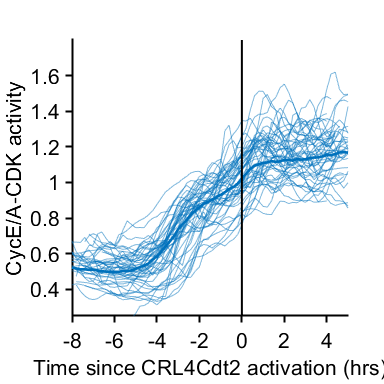


print_pdf([pwd() '\Figs\example_traces'])

## drug effect absolute 

figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
hold on
conds=[1 3 11 13];
POI_align = 3;
cols = lines(4);
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = data.POI(:,POI_align) >= frameDrugAdded + 5 & data.POI(:,POI_align) <= frameDrugAdded + 10 & data.crl_gate & data.cdk_gate;
    if mod(c,2) == 0
        inds = inds & data.YFP1 > 2^9 ;
    end
    fprintf('Cond %d, number of traces %d',i,sum(inds))
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align);
    for j=1:size(ydata,1)
        ydata(j,:) = ydata(j,:);
    end
    
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
%     errorbar((frames)/framesPerHr,medSig,2*semCRL,'LineWidth',1.5);
%     plot((frames)/framesPerHr,medSig,'LineWidth',1.5);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'LineWidth',1.5,'Color',cols(i,:)});
end

Cond 1, number of traces 167

Cond 2, number of traces 145

Cond 3, number of traces 239

Cond 4, number of traces 119

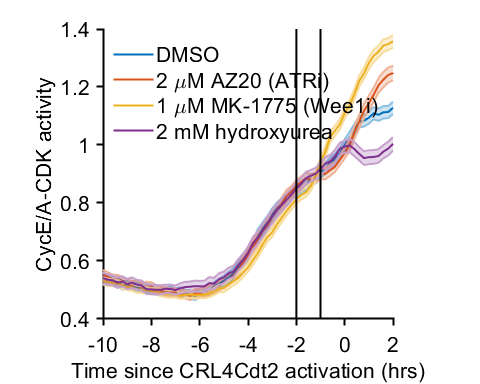


xlabel('Time since CRL4Cdt2 activation (hrs)');
            ylabel('CycE/A-CDK activity');
%legend(conditions(conds,1));
legend({'DMSO','2 \muM AZ20 (ATRi) ','1 \muM MK-1775 (Wee1i)','2 mM hydroxyurea'})
xlim([-10 2]); 
xticks([-10:2:2])
ylim([.4 1.4]);
%ylim([.5 1.5])
vline([-1 -2],'k')
axis square

set(findall(gcf,'-property','FontSize'),'FontSize',16)
set(gca,'linewidth',1.5)
%set(findall(gca, 'Type', 'Line'),'LineWidth',1);
legend boxoff
print_pdf([pwd() '\Figs\compare drugs'])

## Median cdk traces aligned crl

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
hold on
conds=[1 2 13];
POI_align = 3;
colors = [0 113 188; 193 39 45; 0 0 0]/255;

colorval = [1 2 3];
pattern = {'-','-','--','--'}; 

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = data.POI(:,POI_align) > frameDrugAdded & data.crl_gate & data.cdk_gate;
    if mod(c,2) == 0
        inds = inds & data.YFP1 > 2^9 ;
    end
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align);
    for j=1:size(ydata,1)
        ydata(j,:) = ydata(j,:) - ydata(j,POI(j));
    end
    
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
%     errorbar((frames)/framesPerHr,medSig,2*semCRL,pattern{i},'LineWidth',1.5,'Color',colors(colorval(i),:));
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{pattern{i},'Color',colors(colorval(i),:),'LineWidth',1.5});
    fprintf('Cond %d, number of traces %d',i,sum(inds))

end

Cond 1, number of traces 534

Cond 2, number of traces 336

Cond 3, number of traces 395


ylabel({'\DeltaCycE/A-CDK activity' 'from S phase start (AU)'});xlabel('Time since CRL4Cdt2 activation (hrs)');
%legend(conditions(conds,1));
legend({'DMSO/ND-Cdt1-','DMSO/ND-Cdt1+','HU/ND-Cdt1-','HU/ND-Cdt1+'})

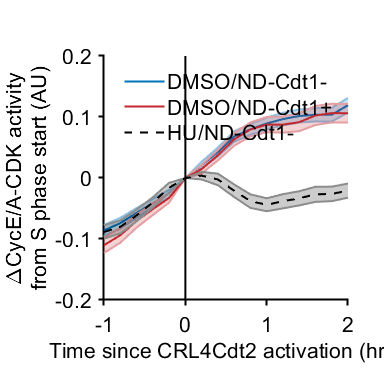

xlim([-1 2]); 
ylim([-.2 .2]);
%ylim([.5 1.5])
vline(0,'k')
axis square

set(findall(gcf,'-property','FontSize'),'FontSize',16)
set(gca,'linewidth',1.5)
%set(findall(gca, 'Type', 'Line'),'LineWidth',1);
legend boxoff
print_pdf([pwd() '\Figs\compare_cdk_mean'])

**Compare histograms **

conds = [1 2];

yval = 'YFP1';

gateVals = {};
rangeVals = {[2^2 2^10]}; 

data = {};

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','xlabel','log2[Cdt1 (RFU)]','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


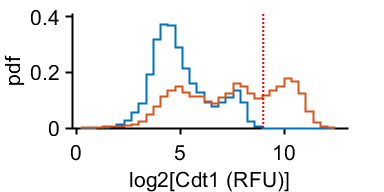

% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
vline([ 9])
print_pdf([pwd() '\Figs\cdt1hists.pdf'])


data

data = 1×2 cell array
    {4674×1 double}    {8559×1 double}
